### Set up parameters for 3D BD simulation and optimization

        Num of run per conditon 

        step size and gap for optimization (grid search)

        metric for similarity quantification

        weight ratio and method for weight matirx 

Num_run = 50;
StepSize_grid = (10:5:30);
Gap_grid = (25:5:180);     %(25:5:180)
score_w1 = 0.5;
score_w2 = -120;


Segment map into 

: nucloid (blue), cytoplasm (yellow) and outside of cell (red)

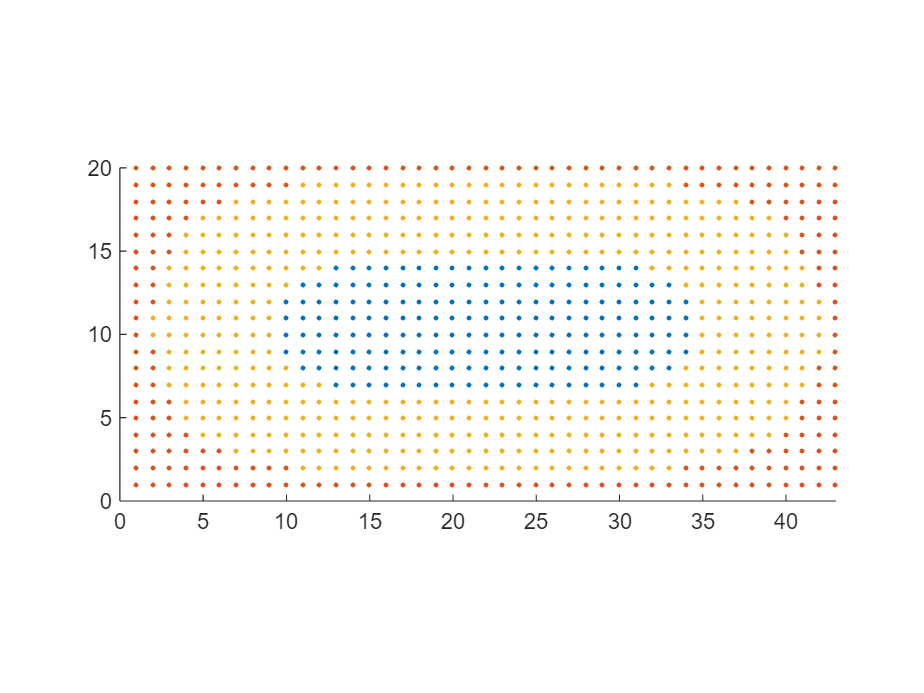

[coord_in_nuc,coord_in_cyto,coord_out_cell] =...
    Map_Segment(spMap,cell_outline,anchor_spMap,...
    num_pix_y,aspt_ratio,convert_factor,'on');
SaveFigure(result_folder,'Map segmentation',...
    gcf, {'fig','png','svg'},[])

% weight matrix for spMap comparision (cytoplasmic region)
weight_matrix1 = Weight_Cmp_spMap(spMap_cnt,...
    {coord_in_nuc,coord_in_cyto,coord_out_cell},...
    [0,1,0],[1,1,1],'linear');

% weight matrix for spMap comparision (pattern)
weight_matrix2 = Weight_Cmp_spMap(spMap_cnt,...
    {coord_in_nuc,coord_in_cyto,coord_out_cell},...
    [1.25,1,0],[1,1,1],'linear');

Simulation loop and similarity evaluation

tic
Store_similarity = cell(length(StepSize_grid),1);
num_agl_seg = 6;
deter_score = [];
Simu_Traj_final = [];

for k = 1:length(StepSize_grid)
    StepSize = StepSize_grid(k);
    Store_result = BD_Simu_batchGen(Num_run,StepSize,[],...
        scale_bar,Ro,Lo,kb_nuc_spMap,anchor_spMap,...
        'on','Collision',...
        floor((max(StepSize_grid)/StepSize)^1.2)*1e5);
    
    buff = cell(1,length(Store_result));
    for j = 1:length(Store_result)
        buff{j} = Store_result{j}(:,1:3);
    end
    Store_result = buff;

    % Data Augmentation
    % rotate coordinates from simulation
    Store_result = SimuTraj_RotAug(Store_result,num_agl_seg);

    Similarity_sp = zeros(length(Gap_grid),6);
    for i = 1:length(Gap_grid)
        % Generate spMap with simulated trajectories 
        % with different Gap for comparison 
        [Simu_spMap,~] = ...
        Spatial_Displacement_Simu(...
        Store_result,Gap_grid(i),num_pix_y,aspt_ratio,...
        scaling_width,scaling_length,scale_bar,0.02,...
        'on','off');
    
        [sp_L2_unweighted, sp_L2, sp_L2_adj,...
        ~, ~, ~] = sp_cmp_similarity(spMap,...
        Simu_spMap, weight_matrix1, coord_in_nuc);
        [~, ~, ~,sp_SSIM, sp_PCC, sp_JSD] =...
            sp_cmp_similarity(spMap, Simu_spMap,...
                              weight_matrix2, coord_in_nuc);
    
        Similarity_sp(i,:) =...
            [sp_L2_unweighted, sp_L2, sp_L2_adj,...
             sp_SSIM, sp_PCC, sp_JSD];
    end
    
    Score = score_w1*Similarity_sp(:,2) +...
            score_w2*Similarity_sp(:,5);

    if isempty(deter_score)
        deter_score = min(Score);
    end
    if deter_score > min(Score)
        deter_score = min(Score);
        Simu_Traj_final = Store_result;
        % min_step = StepSize_grid(k);
        % min_gap = Gap_grid(Score==deter_score);
    end
    Store_similarity{k} = Similarity_sp;
end

clear k StepSize buff j i Simu_spMap Score deter_score 
clear Store_result Similarity_sp
clear sp_L2_unweighted sp_L2 sp_L2_adj sp_SSIM sp_PCC sp_JSD
toc

Elapsed time is 532.214502 seconds.


Optimization result and visualizaiton 

similarity_plot = [];
for i = 1:length(StepSize_grid)
    similarity_plot = cat(2,similarity_plot,...
        score_w1*Store_similarity{i}(:,2)+...
        score_w2*Store_similarity{i}(:,5));
end
clear i

[sel_gap_idx, sel_step_idx] =...
    find(similarity_plot == min(similarity_plot,[],"all"));

sel_stepsize = StepSize_grid(sel_step_idx)

sel_stepsize = 20

sel_gap = Gap_grid(sel_gap_idx)

sel_gap = 125

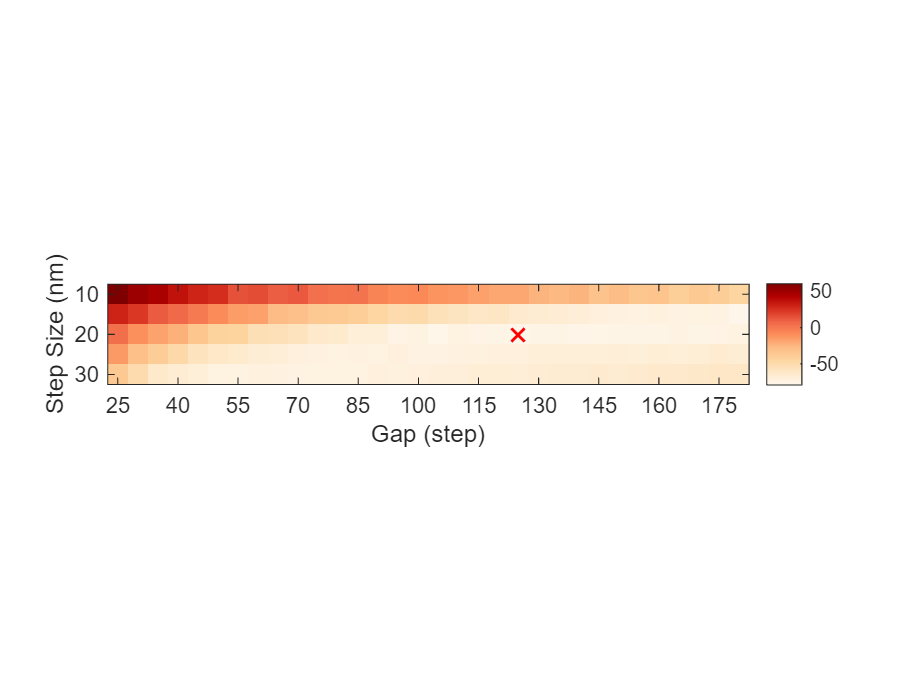


figure
imagesc(similarity_plot.')
ylim([1-0.5 length(StepSize_grid)+0.5])
xlim([1-0.5 length(Gap_grid)+0.5])
yticks((1:2:length(StepSize_grid)));
xticks((1:3:length(Gap_grid)));
yticklabels(string(StepSize_grid(1:2:end)));
xticklabels(string(Gap_grid(1:3:end)));
ylabel('Step Size (nm)')
xlabel('Gap (step)')
hold on
scatter(sel_gap_idx, sel_step_idx,  75,'red','X', 'LineWidth', 1.25)
pbaspect([ length(Gap_grid) length(StepSize_grid) 1])
colormap(slanCM(15))
colorbar
% clim([0 ,min(maxk(similarity_plot(:),15))])


SaveFigure(result_folder,'BD Simu optimization',...
    gcf, {'fig','png','svg'},[])


clear sel_gap_idx sel_step_idx

Comparison between experimental and simulated spMaps

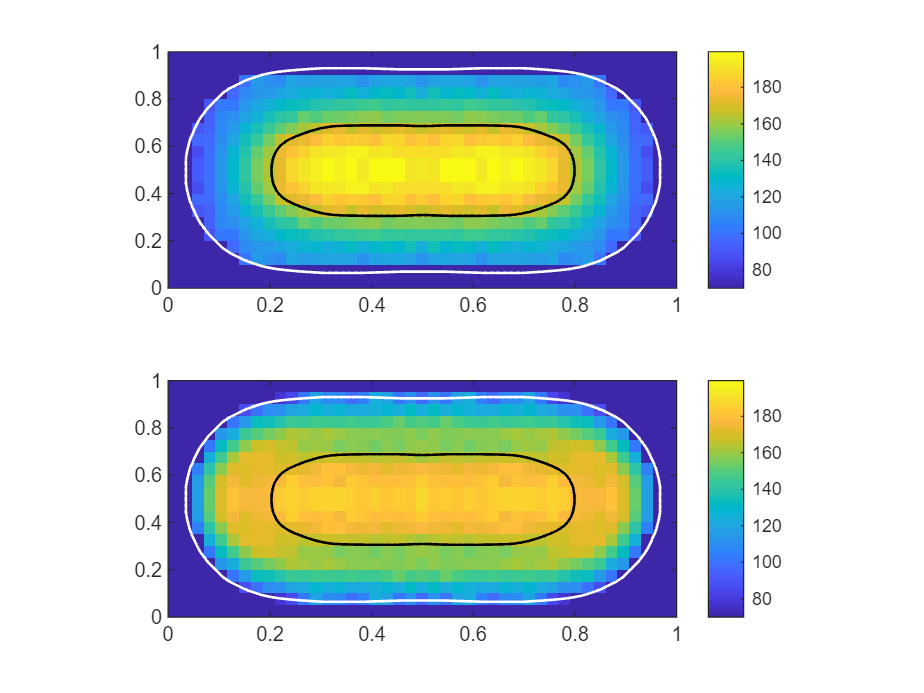

[Simu_spMap,Simu_spatialDisp] =...
    Spatial_Displacement_Simu(Simu_Traj_final,sel_gap,...
    num_pix_y,aspt_ratio,scaling_width,scaling_length,...
    scale_bar,0.02,'on','off');

figure;
clr_range_lb = 1.0*10*floor(min(min(spMap(:)),min(Simu_spMap(:)))/10);
clr_range_rb = 0.95*10* ceil(max(max(spMap(:)),max(Simu_spMap(:)))/10);
clr_map = slanCM('parula');

ax1 = subplot(2,1,1);
Map_plot(ax1, spMap,cell_outline,nuc_contour{1},...
    num_pix_y,'',[clr_range_lb,clr_range_rb],clr_map)
% Spatial Displacement Map from Experiment
ax2 = subplot(2,1,2);
Map_plot(ax2, Simu_spMap,cell_outline,nuc_contour{1},...
    num_pix_y,'',[clr_range_lb,clr_range_rb],clr_map)
% Spatial Displacement Map from Simulation
SaveFigure(result_folder,'spMap comparison',...
    gcf, {'fig','png','svg'},[])


clear clr_range_lb clr_range_rb clr_map ax1 ax2

Organize and save results

OrgResults


All structures saved to L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater\Result_2026_02_12\Results.mat

Raw Data saved to L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater\Result_2026_02_12\RawData.mat


% clear cell_morph Index Lfit Rfit...
%       resd_avg similarity_plot
clearvars -except Open_folder result_folder

# Function

function Map_plot(ax, Map, cell_outline, nuc_outline, num_pix_y, title_name, clr_range, clr_map)

axes(ax);  % Set current axes to ax

aspt_ratio = max(size(Map))/min(size(Map));
imagesc(Map);   
view([0 90]);
hold on;
pbaspect([aspt_ratio, 1, 1]);

% Set colormap and color limits.
colormap(ax, clr_map);
if isempty(clr_range)
    clim([10 * floor(min(Map(:))/10), 10 * ceil(max(Map(:))/10)]);
else
    clim(clr_range)
end

% Define plot limits and tick labels.
num_pix_x = num_pix_y * aspt_ratio;
xlim([0.5, num_pix_x + 0.5]);
xticks(linspace(0.5, num_pix_x + 0.5, 6));
ylim([0.5, num_pix_y + 0.5]);
yticks(linspace(0.5, num_pix_y + 0.5, 6));
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'1','0.8','0.6','0.4','0.2','0'});
hold on
% Plot nucleoid outline (red dashed lines).
plot(nuc_outline(:,1), nuc_outline(:,2), 'k-', 'LineWidth', 1.2);
% Plot cell outline (white solid lines); also connect the last point to the first.
plot(cell_outline(:,1), cell_outline(:,2), 'w-', 'LineWidth', 1.2);
plot([cell_outline(end,1); cell_outline(1,1)], [cell_outline(end,2); cell_outline(1,2)],...
     'w-', 'LineWidth', 1.2);
title(title_name)

colorbar(ax);  % Attach colorbar to the correct subplot
end
